base_dir="data\";
cd(base_dir);

Error using cd
Unable to change current folder to 'C:\Users\Clarisse Alago\Documents\MATLAB\gait-analysis\pre-processing\matlab\data\data' (Name is nonexistent or not a folder).

keypoints= readtable('p1s1.csv');

keypoints

keypoints = 3103×88 table
    x_frame    root_tx    root_ty    root_tz    root_rx    root_ry    root_rz    lowerback_rx    lowerback_ry    lowerback_rz    upperback_rx    upperback_ry    upperback_rz    thorax_rx    thorax_ry    thorax_rz    lowerneck_rx    lowerneck_ry    lowerneck_rz    upperneck_rx    upperneck_ry    upperneck_rz    head_rx    head_ry    head_rz     rshoulderjoint_rx    rshoulderjoint_ry    rshoulderjoint_rz    rhumerus_rx    rhumerus_ry    rhumerus_rz

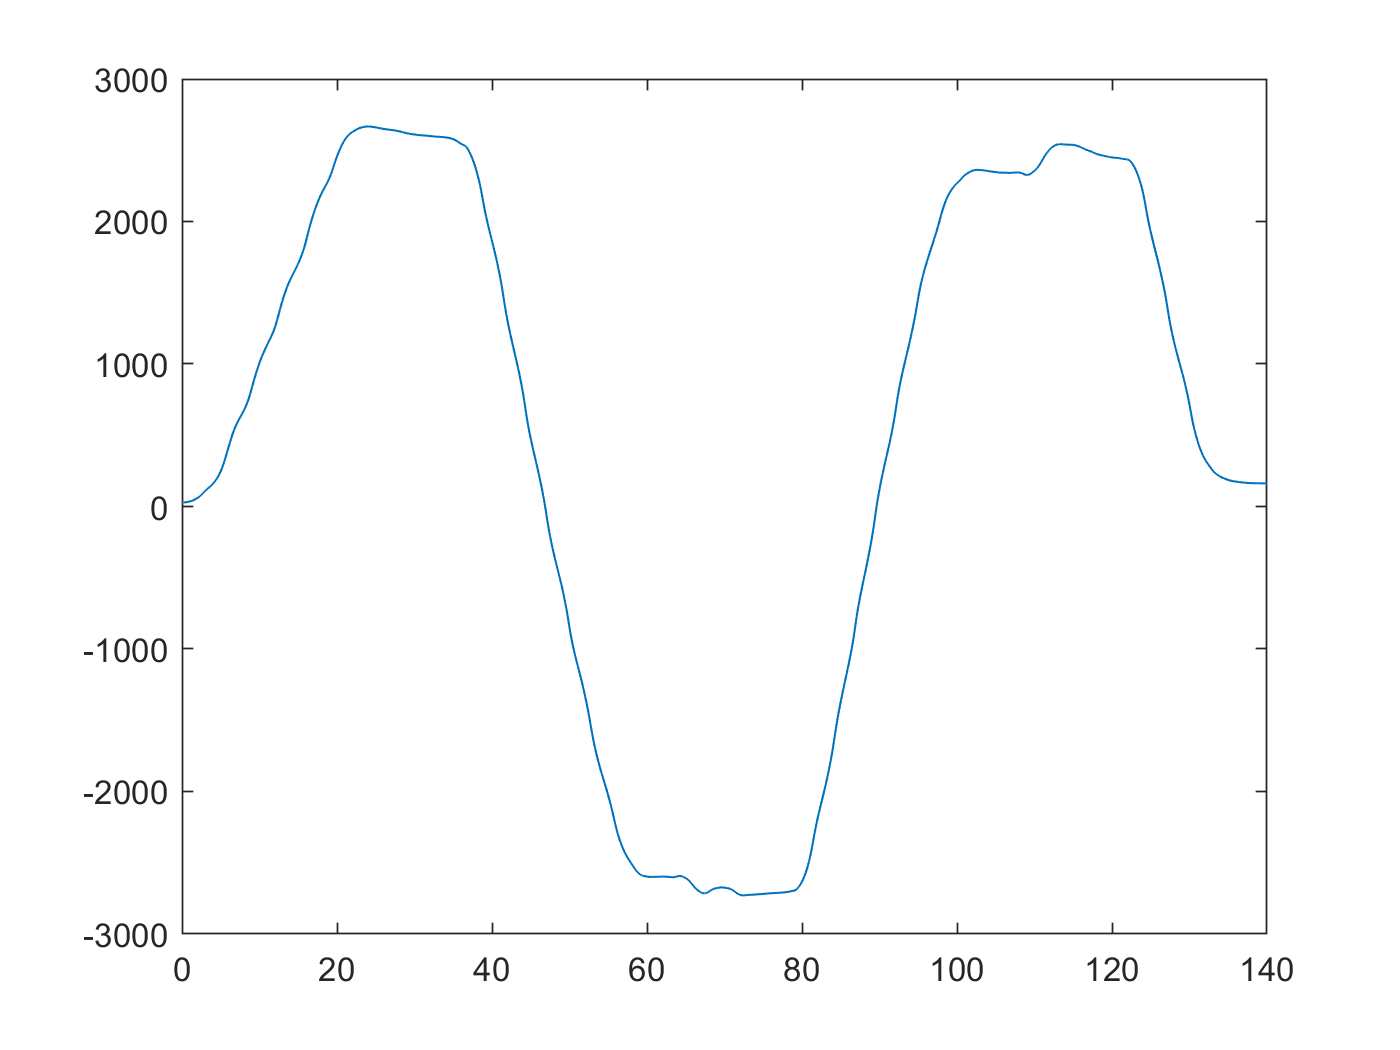

xaxis=linspace(0,140,3103);
plot(xaxis,keypoints.root_tx )

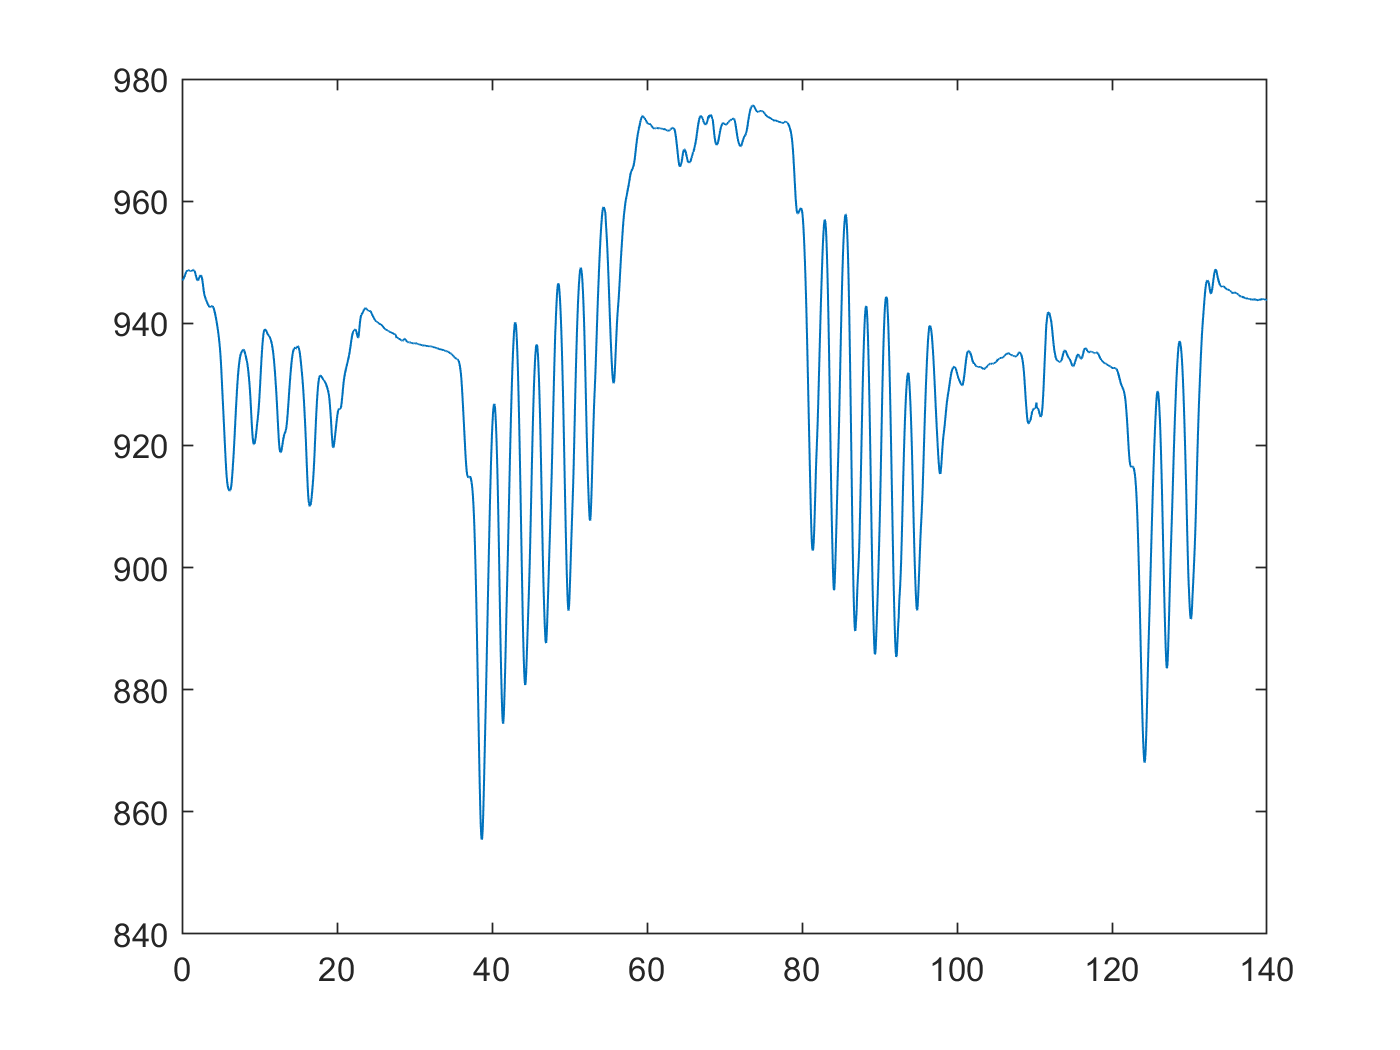

plot(xaxis,keypoints.root_ty)

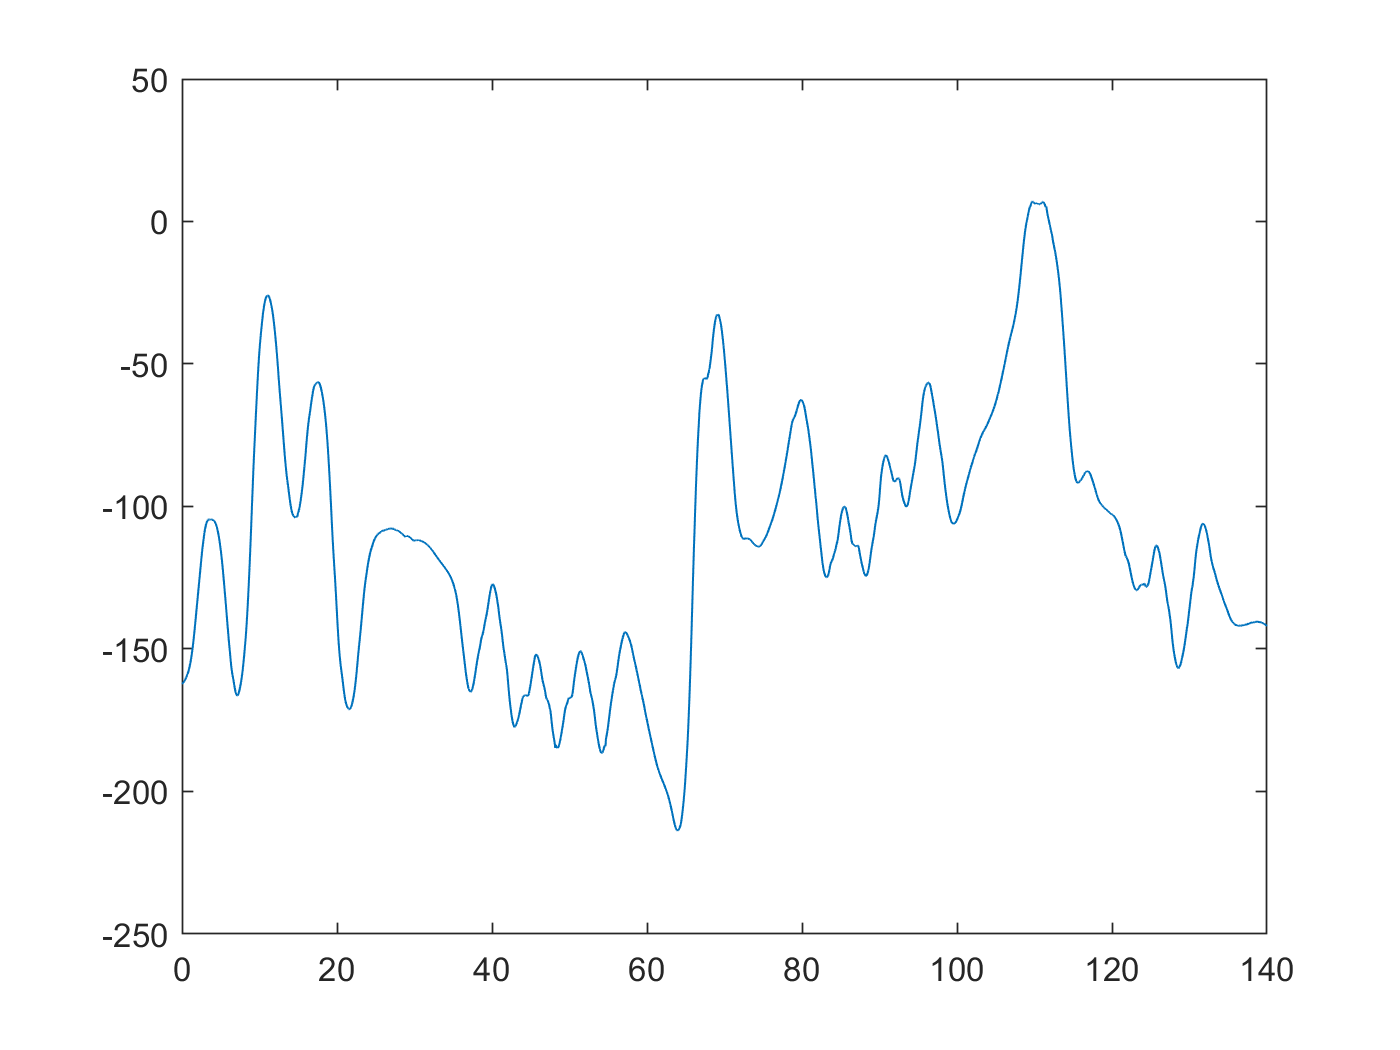

plot(xaxis,keypoints.root_tz)

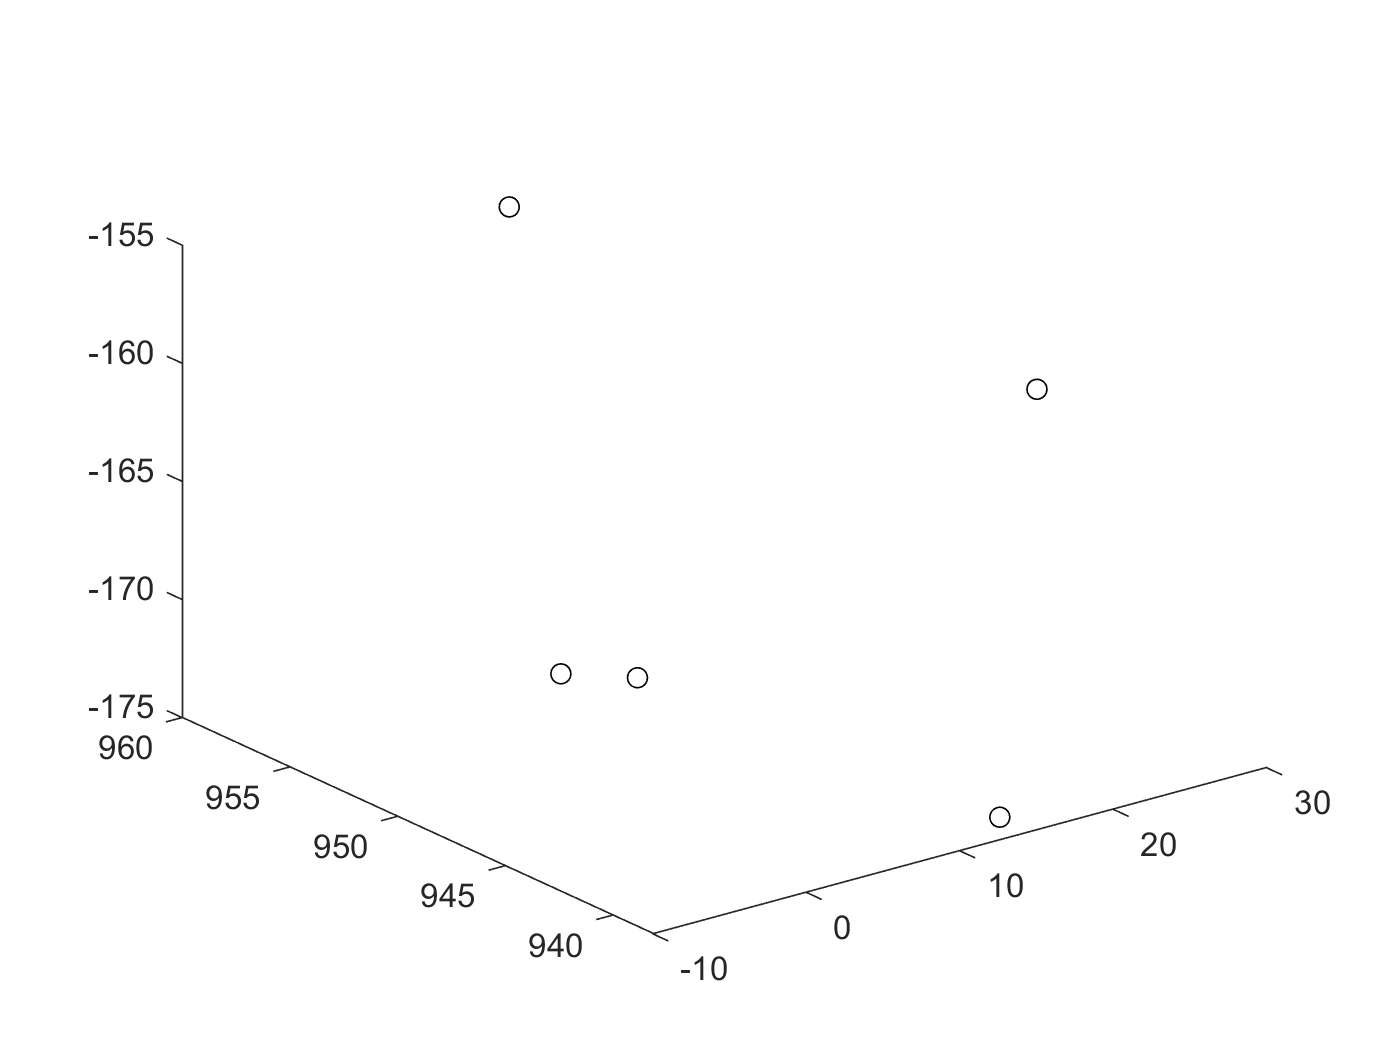

plot3(keypoints.root_tx(1),keypoints.root_ty(1),keypoints.root_tz(1),'ko')
hold on;

plot3(keypoints.root_tx(1)+keypoints.lowerback_rx(1),keypoints.root_ty(1)+keypoints.lowerback_ry(1),keypoints.root_tz(1)+keypoints.lowerback_rz(1),'ko')
plot3(keypoints.root_tx(1)+keypoints.rfemur_rx(1),keypoints.root_ty(1)+keypoints.rfemur_ry(1),keypoints.root_tz(1)+keypoints.rfemur_rz(1),'ko')
plot3(keypoints.root_tx(1)+keypoints.rfemur_rx(1)+keypoints.rtibia_rx(1),keypoints.root_ty(1)+keypoints.rfemur_ry(1)+keypoints.rtibia_ry(1),keypoints.root_tz(1)+keypoints.rfemur_rz(1)+keypoints.rtibia_rz(1),'ko')
plot3(keypoints.root_tx(1)+keypoints.lfemur_rx(1),keypoints.root_ty(1)+keypoints.lfemur_ry(1),keypoints.root_tz(1)+keypoints.lfemur_rz(1),'ko')
plot3(keypoints.root_tx(1)+keypoints.lowerback_rx(1)+keypoints.upperback_rx(1),keypoints.root_ty(1)+keypoints.lowerback_ry(1)+keypoints.upperback_ry(1),keypoints.root_tz(1)+keypoints.lowerback_rz(1)+keypoints.upperback_rz(1),'ko')
hold off